**EE-414 Speech Processing Lab**

**Lab-10**

**AIM**

- Develop a method for the estimation of pitch by the autocorrelation of speech signal.

- Develop a cepstrum pitch estimation method.

- Develop a simple inverse filtering technique(SIFT) pitch estimation method.

- Comparison of all these three methods.

**THEORY:**

Speech signal can be classified into voiced, unvoiced and silence regions. 

1) Voiced: 

- The near periodic vibration of vocal folds is excitation for the production of voiced speech. 

- Majority of speech regions are voiced in nature that include vowels,  semivowels and other voiced components like nasals,

- The voiced regions looks like a near periodic signal in the time domain representation. In a short term , we may treat the voiced speech segments to be periodic for all practical analysis and processing. 

**2) **Unvoiced: 

- Random like excitation

3) Silence:

- There is noexcitation during silence region.

**Pitch of Voiced Sounds:**

- The periodicity associated with voiced segmentsis defined is 'pitch period To' in the time domain and 'Pitch frequency or Fundamental Frequency Fo' in the frequency domain.

- Unless specified, the term 'pitch' refers to the fundamental frequency ' Fo'.

-  Pitch is an important attribute of voiced speech. It contains **speaker-specific information**. It is also needed for speech coding task. Thus estimation of pitch is one of the important issue in speech processing.

 **Methods for estimating pitch:**

There are a large set of methods that have been developed in the speech processing area for the estimation of pitch. 

Among them the three mostly used methods include,

-  autocorrelation of speech

- cepstrum pitch determination

- single inverse technique (SIFT) pitch estimation. 

One success of these methods is due to the involvment of simple steps for the estimation of pitch. Even though autocorrelation method is of theoritical interest, it produces a frame work for SIFT methods.

**PROBLEM STATEMENT**

Record (16kHz, 16bit) the word “**speech signal**”; truncate long silence regions. 

[y,fs]=audioread('phrase.wav');
y = y(:,1);%considering one channel

A. Pitch estimation by autocorrelation method:

- Divide the given speech signal into 30-40ms blocks of speech frames. Find and plot the auto-correlation sequence of a voiced frame and an unvoiced frame. 

%---------Voiced Sound:ee---------------------%
y_voiced = y(ceil(0.475*fs:0.505*fs));
N = length(y_voiced)

N = 481

y_corr_v=autocorrelation(y_voiced,N);
%-----------Unvoiced sound:s------------------%
y_unvoiced = y(ceil(0.275*fs:0.305*fs));
N = length(y_unvoiced)

N = 481

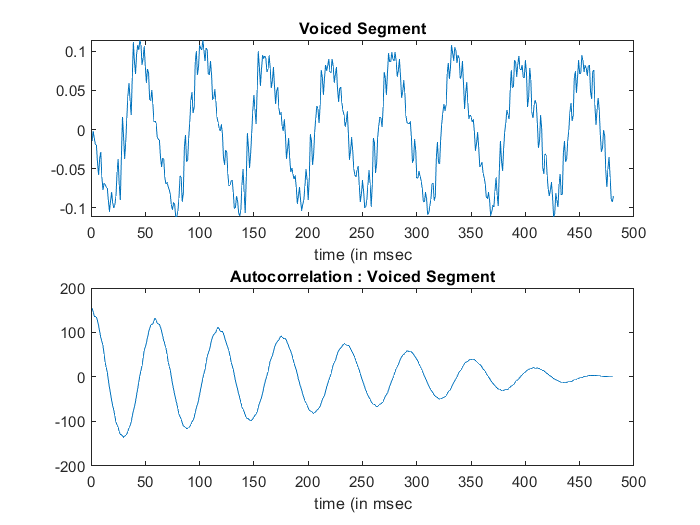

y_corr_uv=autocorrelation(y_unvoiced,N);


figure();
subplot(2,1,1)
plot(y_voiced)
title('Voiced Segment')
xlabel('time (in msec')

subplot(2,1,2)
plot(y_corr_v)
title('Autocorrelation : Voiced Segment')
xlabel('time (in msec')

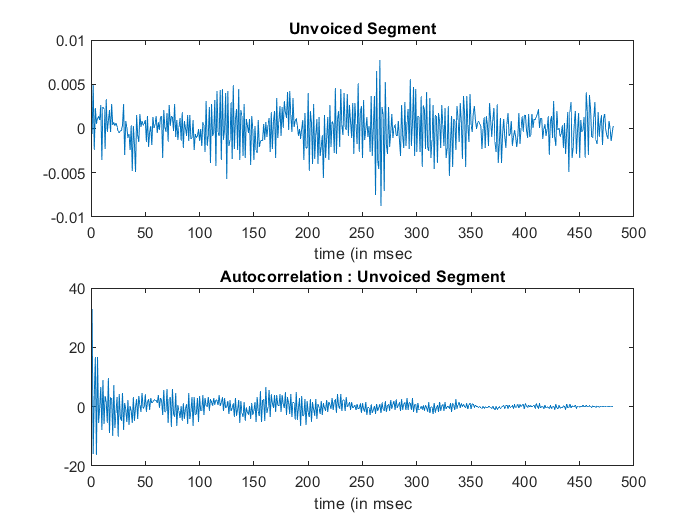

figure();
subplot(2,1,1)
plot(y_unvoiced)
title('Unvoiced Segment')
xlabel('time (in msec')
subplot(2,1,2)
plot(y_corr_uv)
title('Autocorrelation : Unvoiced Segment')
xlabel('time (in msec')

Observations and Comments:

1) The information about pitch period 'To' is more pronounced in the autocorrelation sequence of voiced speech compared to the speech segment itsely.   So,  the second significant peak in the autocorrelation sequence, represents To and can be picked up easily by a simple peak picking algorithm compared to finding 'To' from the speech segment itself. Hence autocorrelation method is preferred over other direct methods of pitch estimation from speech.

2) There is no prominent peak as in the case of unvoiced speech. This is the fundamental distinction between voiced and unvoiced speech.

3) Autocorrelation function of voiced is periodic.

2. Estimate the pitch frequency using this computed auto-correlation for the above  voiced frame and an unvoiced frame. You may set a threshold for a significant peak, and assign zero to pitch frequency if there is no significant peak.

min_pitch = 25;
max_pitch = 400;
%voiced
y_corr_v = y_corr_v./(max(abs(y_corr_v)));
y_corr_v = y_corr_v(min_pitch:max_pitch);
[y_val,y_loc]= max(y_corr_v);
pitch_period = min_pitch + y_loc

pitch_period = 60

pitch_frequency  = fs/pitch_period 

pitch_frequency = 266.6667


%unvoiced
y_corr_uv = y_corr_uv./(max(abs(y_corr_uv)));
y_corr_uv = y_corr_uv(min_pitch:max_pitch);
[y_val,y_loc]= max(y_corr_uv);
pitch_period = min_pitch + y_loc

pitch_period = 162

pitch_frequency  = fs/pitch_period 

pitch_frequency = 98.7654

**Limitation Of Autocorrelation of speech:**

The main limitation of pitch estimation by the auto correlation of speech is that there may be peaks larger than the peak corresponding to the pitch period T0 due to the effect of the vocal tract, As a result there may be picking of wrong peaks and hence wrong estimation of pitch. The approach to minimize such errors is to **separate the vocal tract and excitation source related information** in the speech signal and there use the source information for pitch estimation. The ceptral analysis of speech provides such an approach.

**B. Cepstrum based pitch estimation:**

**Theory:**

The ceptrum of speech is defined as the inverse Fourier transform of the log magnitude spectrum. The cepstrum projects all the slowly varying (corresponds to the vocal tract) components in log magnitude spectrum to the low frequency region and **fast varying components (corresponds to excitation source) to the high frequency regions. **

- Divide the speech into  short segments of 15-20ms frame size. Compute the cepstrum of the speech segment in the quefrency domain for each of these frames  and plot for one voiced frame.

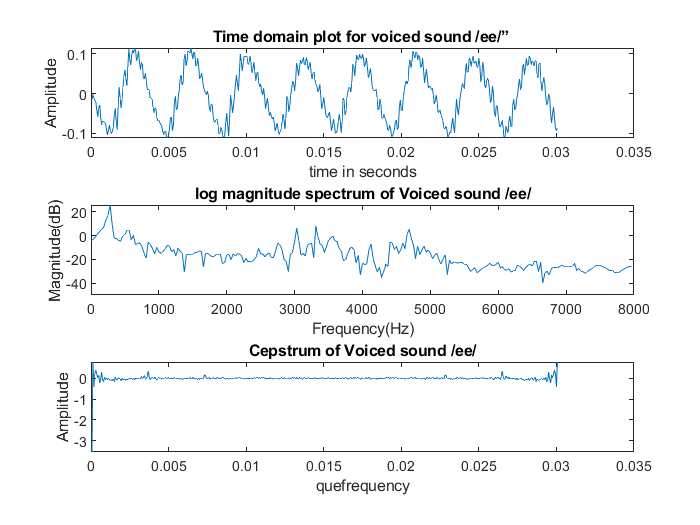


t_ee = (1:length(y_voiced))/fs;
t_s = (1:length(y_unvoiced))/fs;

%-----------------Voiced--------------------------%
%ploting time domain plot for voiced segment /ee/
figure ;
subplot(3,1,1)
plot(t_ee,y_voiced);
xlabel('time in seconds');
ylabel('Amplitude');
title('Time domain plot for voiced sound /ee/” ')

%plotting log-magnitude spectrums
%for voiced sound /ee/
[freq,Y] = mag_spec(y_voiced,fs);

subplot(3,1,2)
plot(freq,20*log10(abs(Y)))
title('log magnitude spectrum of Voiced sound /ee/');
xlabel('Frequency(Hz)');
ylabel('Magnitude(dB)');

%plotting cepstrum 
%for voiced sound /ee/
N = 160;
y1_ee = y_voiced.*hamming(length(y_voiced));
y_ee_cep = ifft(log(abs(fft(y1_ee))));
subplot(3,1,3)
plot(t_ee,y_ee_cep)
title( 'Cepstrum of Voiced sound /ee/');
xlabel('quefrequency');
ylabel('Amplitude');

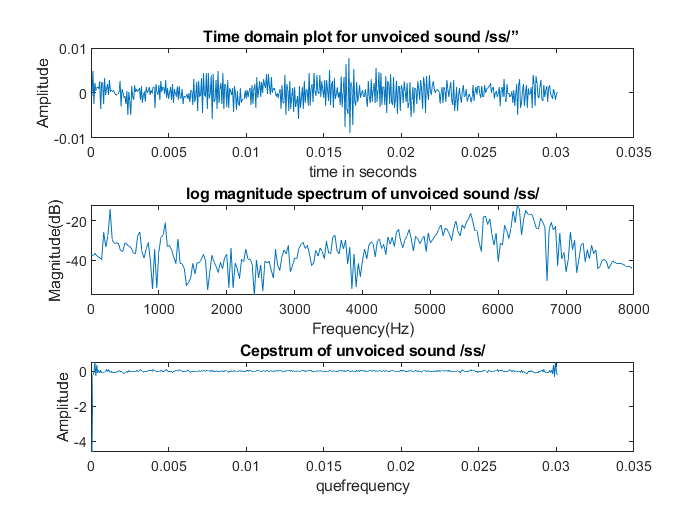

%--------------------Unvoiced Sound----------------%
%ploting time domain plot for Unvoiced
figure ;
subplot(3,1,1)
plot(t_s,y_unvoiced);
xlabel('time in seconds');
ylabel('Amplitude');
title('Time domain plot for unvoiced sound /ss/” ')

%plotting log-magnitude spectrums
%for voiced sound /ee/
[freq,Y] = mag_spec(y_unvoiced,fs);

subplot(3,1,2)
plot(freq,20*log10(abs(Y)))
title('log magnitude spectrum of unvoiced sound /ss/');
xlabel('Frequency(Hz)');
ylabel('Magnitude(dB)');

%plotting cepstrum 
%for unvoiced sound /ss/
y1_ss = y_unvoiced.*hamming(length(y_unvoiced));
y_ss_cep = ifft(log(abs(fft(y1_ss))));
subplot(3,1,3)
plot(t_s,y_ss_cep)
title( 'Cepstrum of unvoiced sound /ss/');
xlabel('quefrequency');
ylabel('Amplitude');

2. Estimate the pitch period by the high time liftering of the cepstrum of the voiced speech. 

y_ee_lift=y_ee_cep(1:length(y_ee_cep)/2);%as cepstrum is symmetric we are taking half of the cepstral coefficiets

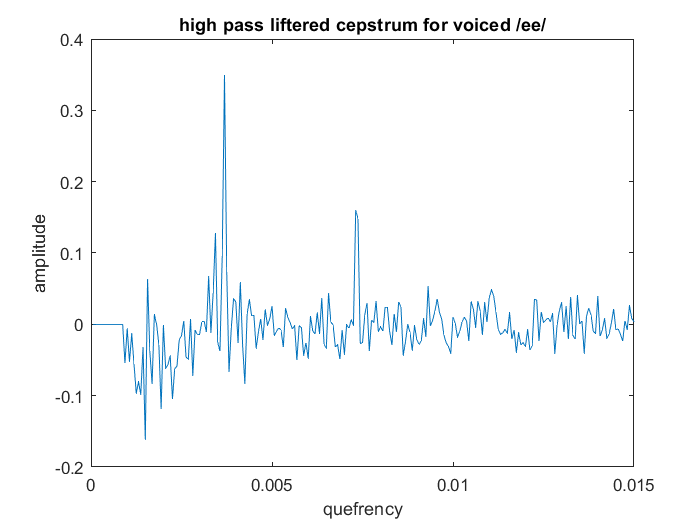

%High-time liftering
L_high(15:length(y_ee_lift))=1 ;
y_ee_highpass =real(y_ee_lift.*(L_high.')) ;
t_ee_highpass = (1:length(y_ee_highpass))/fs;
figure;
plot(t_ee_highpass,y_ee_highpass);
xlabel('quefrency');
ylabel('amplitude');
title('high pass liftered cepstrum for voiced /ee/')

% Pitch estimation
[M,I]=max(y_ee_highpass);   % finding the peak in high pass liftered cepstrum
pitch_period_voiced = I

pitch_period_voiced = 59

Fo = (1/I)*fs ;            % converting pitch period in samples to frequency in hz
Pitch_frequency_voiced = Fo

Pitch_frequency_voiced = 271.1864

3. Estimate the pitch period by the high time liftering of the cepstrum of the unvoiced speech.

y_ss_lift=y_ss_cep(1:length(y_ss_cep)/2);

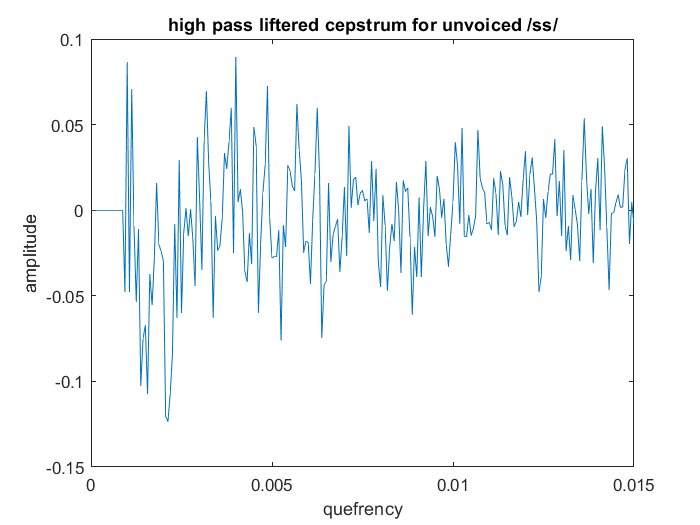

%High-time liftering
L_high(15:length(y_ss_lift))=1 ;
y_ss_highpass =real(y_ss_lift.*(L_high.')) ;
t_ss_highpass = (1:length(y_ss_highpass))/fs;
figure;
plot(t_ss_highpass,y_ss_highpass);
xlabel('quefrency');
ylabel('amplitude');
title('high pass liftered cepstrum for unvoiced /ss/')

% Pitch estimation
[M,I]=max(y_ss_highpass);   % finding the peak in high pass liftered cepstrum
pitch_period_unvoiced = I

pitch_period_unvoiced = 64

Fo = (1/I)*fs ;            % converting pitch period in samples to frequency in hz
Pitch_frequency_unvoiced = Fo

Pitch_frequency_unvoiced = 250

**Obervations and Comments:**

- The initial few values in the cepstrum typically 13-15 cepstral values represent the vocal tract information. The large peak present after these initial values represent the excitation information. In particular, the pitch period T0 starting from the zeroth value in number of samples. As a result the peaks that may be occuring in case of autocorrelation analysis get naturally eliminated in cepstrum pitch determination. Hence the merit of the cepstrum method.

- It may be observed that there is no prominent peak in case of ceptrum of unvoiced speech after the 13-15 initial cepstral values. This is the main distinction between cepstrum of voiced and unvoiced speech. 

- The cepstral approach does not have large peaks as in the autocorrelation case that may interfere with the estimation of pitch.

**C. Pitch estimation by Simple Inverse Filtering Technique (SIFT):**

**THEORY:**

- Based on the linear prediction (LP) analysis of speech.

-  The SIFT performs autocorrelation of the LP residual than speech directly. More of the vocal tract information is modeled by the LP coefficients and hence the LP residual mostly contains the excitation source information. The autocorrelation of LP residual will therefore have unambiguous peaks representing the pitch period 'T0' information.

- Take a 30 ms voiced speech segment and compute the Linear Prediction (LP) residual by LP analysis.  Perform autocorrelation on the LP residual. Estimate of pitch period from the autocorrelation sequence of the LP residual. 

%voiced
N = length(y_voiced); %length of sequence
w = hamming(N);
y_win = y_voiced.*w;
p =10;
y_corr=autocorrelation(y_win,N);  %autocorrelation
A = y_corr(1:p);  %R
r = y_corr(2:(p+1));
A = toeplitz(A);
L = -inv(A)*r';
L = L';
LP_coeff(1,1:length([1,L])) =[1,L]

LP_coeff =     1.0000   -1.6479    2.1456   -2.5203    1.6947   -1.3216    0.4889    0.0067    0.1922   -0.0870    0.1294


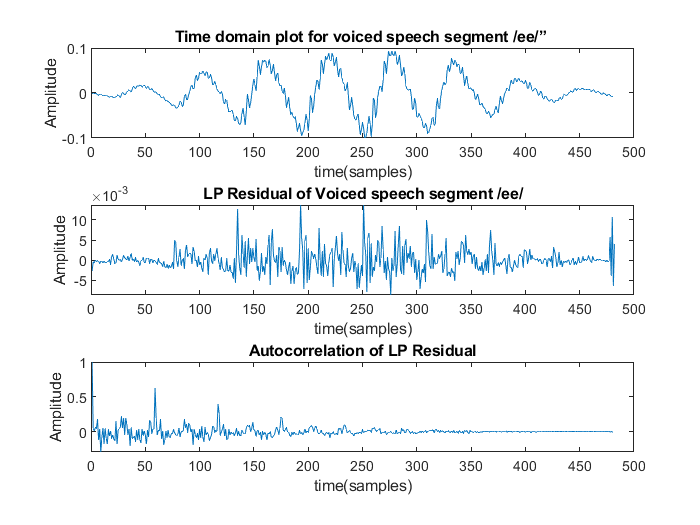


y_res = conv(y_win,LP_coeff);%Inverse filtering;
y_res = y_res(round(p/2):length(y_res)-round(p/2));%removing additional samples caused due to convolution

y_res_corr = autocorrelation(y_res,N);
y_res_corr_v = y_res_corr./(max(abs(y_res_corr)));


%ploting time domain plot for voiced segment /ee/
figure ;
subplot(3,1,1)
plot(y_win);
xlabel('time(samples)');
ylabel('Amplitude');
title('Time domain plot for voiced speech segment /ee/” ')

subplot(3,1,2)
plot(y_res)
title('LP Residual of Voiced speech segment /ee/');
xlabel('time(samples)');
ylabel('Amplitude');

subplot(3,1,3)
plot(y_res_corr_v)
title('Autocorrelation of LP Residual');
xlabel('time(samples)');
ylabel('Amplitude');


min_pitch = 25;
max_pitch = 400;
y_res_corr_p = y_res_corr(min_pitch:max_pitch);
[y_val,y_loc]= max(y_res_corr_p);
pitch_period = min_pitch + y_loc

pitch_period = 60

pitch_frequency  = fs/pitch_period 

pitch_frequency = 266.6667

2. Perform the same for the unvoiced speech segment also.

%unvoiced
N = length(y_unvoiced); %length of sequence
w = hamming(N);
y_win = y_unvoiced.*w;
p =10;
y_corr=autocorrelation(y_win,N);  %autocorrelation
A = y_corr(1:p);  %R
r = y_corr(2:(p+1));
A = toeplitz(A);
L = -inv(A)*r';
L = L';
LP_coeff(1,1:length([1,L])) =[1,L]

LP_coeff =     1.0000    0.3660   -0.1551   -0.9919    0.0072   -0.2642    0.2503   -0.0304    0.3048   -0.1227    0.0343


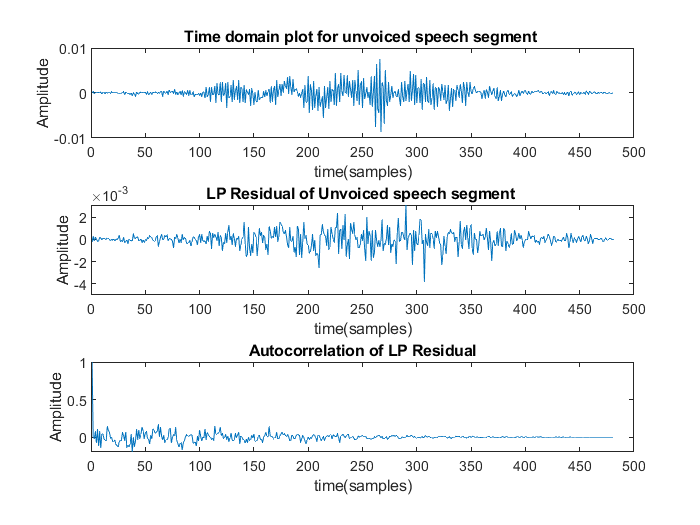


y_res = conv(y_win,LP_coeff);%Inverse filtering;
y_res = y_res(round(p/2):length(y_res)-round(p/2));%removing additional samples caused due to convolution

y_res_corr = autocorrelation(y_res,N);
y_res_corr_uv = y_res_corr./(max(abs(y_res_corr)));


%ploting time domain plot for voiced segment /ee/
figure ;
subplot(3,1,1)
plot(y_win);
xlabel('time(samples)');
ylabel('Amplitude');
title('Time domain plot for unvoiced speech segment ')

subplot(3,1,2)
plot(y_res)
title('LP Residual of Unvoiced speech segment ');
xlabel('time(samples)');
ylabel('Amplitude');

subplot(3,1,3)
plot(y_res_corr_uv)
title('Autocorrelation of LP Residual');
xlabel('time(samples)');
ylabel('Amplitude');


min_pitch = 25;
max_pitch = 400;
y_res_corr_p = y_res_corr(min_pitch:max_pitch);
[y_val,y_loc]= max(y_res_corr_p);
pitch_period = min_pitch + y_loc

pitch_period = 63

pitch_frequency  = fs/pitch_period

pitch_frequency = 253.9683

**Obervations and Comments:**

- As can be observed for voiced segments, there is a prominent peak at the pitch period 'T0' and there are no other peaks that interfere with its peak. This is the merit of SIFT over autocorrelation of speech.

- In unvoiced speech, its LP residual and the autocorrelation of the LP residual,  no prominent peak as in the case of voiced speech 

**D. Comparison of pitch estimation methods:**

- Plot the entire input speech signal and it’s pitch contours  estimated using autocorrelation,  cepstrum and SIFT based pitch estimation methods.

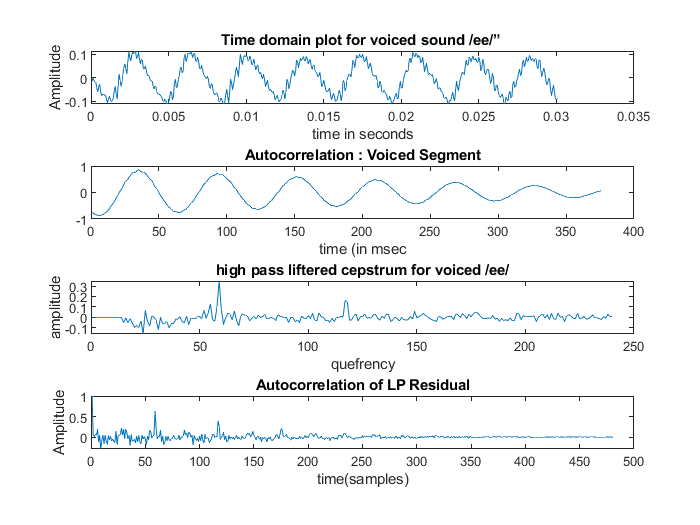

%comparison for voiced segment
figure();
subplot(4,1,1)
plot(t_ee,y_voiced);
xlabel('time in seconds');
ylabel('Amplitude');
title('Time domain plot for voiced sound /ee/” ')
%Autocorrelation
subplot(4,1,2)
plot(y_corr_v)
title('Autocorrelation : Voiced Segment')
xlabel('time (in msec')
%Cepstrum
subplot(4,1,3)
plot(y_ee_highpass);
xlabel('quefrency');
ylabel('amplitude');
title('high pass liftered cepstrum for voiced /ee/')
%SIFT
subplot(4,1,4)
plot(y_res_corr_v)
title('Autocorrelation of LP Residual');
xlabel('time(samples)');
ylabel('Amplitude');

**Observations and Comments:**

- All the methods show a peak at the pitch period 'T0'. 

- Cepstral and the SIFT method sequences have less ambiguity compared to autocorrelation of speech. Hence either cepstrum or SIFT method is equally preferable for the estimation of pitch.

-  In case of speech coding, LP analysis  is mostly used and hence SIFT method is prefered over Cepstrum pitch estimation. 

- Alternatively, in tasks like speaker recognition, since cepstral analysis is used for the feature extraction tasks, ceptrum pitch estimation may be employed.

Frame_size = 30;%Input: Frame-size in millisecond
Frame_shift = 10;%Input: Frame-shift in millisecond
max_value=max(abs(y));
y=y/max_value;
window_period=Frame_size/1000;
shift_period=Frame_shift/1000;
pitch_freq=0;
t=1/fs:1/fs:(length(y)/fs);
figure;
subplot(4,1,1);
plot(t,y);
title('Speech signal waveform');
window_length = window_period*fs;
sample_shift = shift_period*fs;
sum1=0;
energy=0;
auto_correlation=0;
for i=1:(floor((length(y))/sample_shift)-ceil(window_length/sample_shift))
  k=1;yy=0;
  for j=(((i-1)*sample_shift)+1):(((i-1)*sample_shift)+window_length)
    yy(k)=y(j);
    k=k+1;
  end
  for l=0:(length(yy)-1)
    sum1=0;
    for u=1:(length(yy)-l)
      s=yy(u)*yy(u+l);
      sum1=sum1+s;
    end
    autocor(l+1)=sum1;
    auto_correlation(l+1,i)= autocor(l+1);
  end
  auto=autocor(21:240);
  max1=0;
  for uu=1:220
    if(auto(uu)>max1)
      max1=auto(uu);
      sample_no=uu;
    end
  end
  pitch_freq(i)=1/((20+sample_no)*(1/fs));
end
[rows,cols]=size( auto_correlation);
kkk=1/fs:shift_period:(cols*shift_period);
subplot(4,1,2);
plot(kkk,pitch_freq,'.');
title('Pitch Contour obtained by autocorrelation of speech signal ');
%Code to generate the pitch contour of a speech signal using Cepstrum pitch estimation method
pitch_freq1=0;o=1;
Frame_size=30;pitch_freq = 0;
Frame_shift=10;
max_value=max(abs(y));
y=y/max_value;
window_period=Frame_size/1000;
shift_period=Frame_shift/1000;
t=1/fs:1/fs:(length(y)/fs);
window_length = window_period*fs;
sample_shift = shift_period*fs;
sum1=0;energy=0;
auto_correlation=0;
for i=1:(floor((length(y))/sample_shift)-ceil(window_length/sample_shift))
  k=1;yy=0;
  for j=(((i-1)*sample_shift)+1):(((i-1)*sample_shift)+window_length)
    yy(k)=y(j);
    k=k+1;
  end
     
     t=1/fs:1/fs:(length(yy)/fs);
    t=(t(1:length(t)/2))*1000;
    dfty=abs(fft(yy));
dfty1=dfty(1:length(dfty)/2);
tt=linspace(1/fs,fs,length(dfty1));
for i=1:length(dfty)
  if (dfty(i)==0)
    dfty(i)=1D-16;
  end
end
dftylog=log10(dfty);
dftylog1=dftylog(1:length(dftylog)/2);
yy=10*dftylog1;

%xtitle('Log Magnitude Spectrum','frequency in Hz');
real_ceps=abs(ifft(dftylog));
real_ceps=real_ceps(1:length(real_ceps)/2);
%real_ceps=[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 2 3 4 5 6 5 4 3 2 1];
real_ceps_pitch=real_ceps(16:length(real_ceps));


max1=max(real_ceps_pitch);
%max1=0;
for uu=1:length(real_ceps_pitch)
  uu;
  real_ceps_pitch(uu);
  max1;
    if(real_ceps_pitch(uu)==max1)
      %max1=real_ceps_pitch(uu);
      sample_no=uu;
    end
  end
  pitch_freq1=1/((16+sample_no)*(1/fs));
  pitch_freq(o)= pitch_freq1;
  o=o+1;
  pitch_freq(i)=1/(16+sample_no);
end
kk=1/fs:shift_period:(length(pitch_freq)*shift_period);
subplot(4,1,3);
plot(kk,pitch_freq,'.');
title('Pitch Contour obtained by cepstrum pitch estimation method');

%pitch estimation using SIFT
sum1=0;
energy=0;
Fs=fs;
pitch_freq=0

pitch_freq = 0

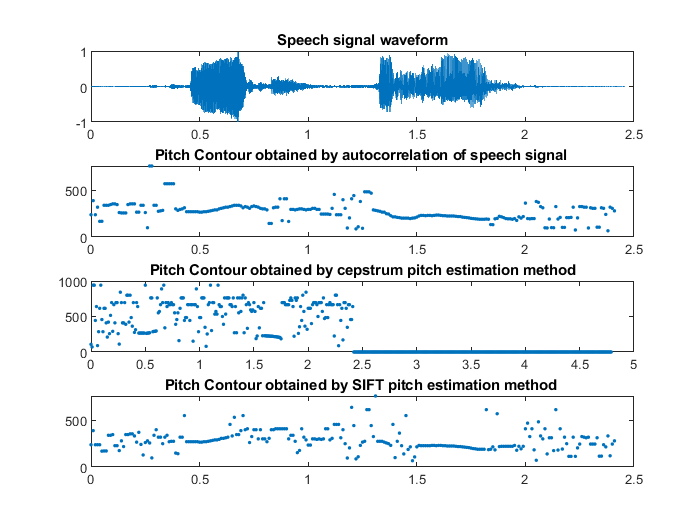

autocorrelatio=0;
for i=1:(floor((length(y))/sample_shift)-ceil(window_length/sample_shift))
    k=1;yy=0;
    for j=(((i-1)*sample_shift)+1):(((i-1)*sample_shift)+window_length)
        yy(k)=y(j);
        k=k+1;
    end
    
    yy=yy/(1.01*abs(max(yy)));
    t=(1/Fs:1/Fs:(length(yy)/Fs))*1000;
    P=10;
    ycorr=autocorrelation(yy,480);
    
    ycorr=ycorr./(abs(max(ycorr)));
    y_A=ycorr(1:P);
    b=ycorr(2:(P+1));
    A=toeplitz(y_A);
    %%By direct matix soving method
    L=-inv(A)*b';
    L=L';
    LPCoeffs(1,1:length([1,L])) = [1,L];
    y5=conv(yy,LPCoeffs);
    y5=y5(round(P/2):length(y5)-round(P/2)-1);
    
    for l=0:(length(y5)-1)
        sum1=0;
        for u=1:(length(y5)-l)
            s=y5(u)*y5(u+l);
            sum1=sum1+s;
        end
        autocor(l+1)=sum1;
        autocorrelatio(l+1,i)= autocor(l+1);
    end
    auto=autocor(21:480);
    max1=0;
    for uu=1:460
        if(auto(uu)>max1)
            max1=auto(uu);
            sample_no=uu;
        end
    end
    pitch_freq(i)=1/((20+sample_no)*(1/Fs));
end
[rows,cols]=size( autocorrelatio);
kkk=1/Fs:shift_period:(cols*shift_period);
subplot(4,1,4);
plot(kkk,pitch_freq,'.');
title('Pitch Contour obtained by SIFT pitch estimation method ');

The random values in the pitch contours compared to the unvoiced and silence regions. The random values in the unvoiced and silence regions. The continuous segments correspond to the voiced regions. Most of the random values can be eliminated by the voiced/ unvoiced classification. In name of the voiced regions, the autocorrelation of speech has same random values due to the sp... peak picking.

Functions

function [a]=autocorrelation(speechsignal,N)
y=speechsignal;
window_length=N;
max_value=max(abs(y));
y=y/max_value;
y=y(1:window_length);
sum=0;
autocorrelate=[];
for l=0: (length(y)-1)
    sum=0;
    for u=1:length(y)-l
        s=y(u)*y(u+l);
        sum=sum+s;
    end
    autocorrelate(l+1)=sum;
end
a=autocorrelate;
end

function [freq,Y] = mag_spec(y,fs)
N=length(y);% length of sound /a/
N1=2^nextpow2(N);
freq=fs*(0:N1/2-1)/N1; %Frequency axis for s
Y = fft(y,N1);
Y = Y(1:N1/2);
end
